successful_trials_val = strfind(triggerValues, [100,150,190,223]);
succ_trial_num = length(successful_trials_val);
fprintf ('number of successful trials = %d\n', succ_trial_num);

number of successful trials = 138


% cluster trials
reward_period_sam = triggerTimes(successful_trials_val + 2) - triggerTimes(successful_trials_val + 1) + 1;
reward_period_time = double(reward_period_sam) / fs;
reward_period_time = round(reward_period_time, 1)

reward_period_time =     0.1000    0.1000    0.1000    0.1000    0.2000    0.1000    0.1000    0.2000    0.1000    1.0000    0.1000    0.1000    0.2000    0.1000    0.1000    0.2000    0.1000    0.1000    0.1000    0.1000    0.1000    0.2000    0.2000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    1.0000    0.1000    0.1000    0.2000    0.1000    0.2000    0.1000    0.1000    0.1000    0.1000    0.1000    0.2000    0.1000    0.1000    0.1000    0.1000    1.0000    0.1000    0.1000


start_idx = triggerTimes(successful_trials_val);
end_idx = triggerTimes(successful_trials_val + 1);

eye_tracks = eye_track_data(rawData, start_idx, end_idx, reward_period_time);

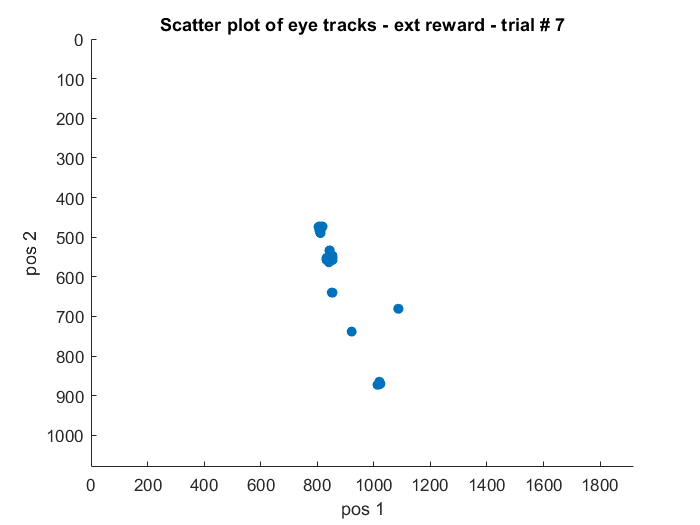

Number of samples = 89742

figure;
scatter_plot_eyeTrack(eye_tracks, "ext", 7, 0);

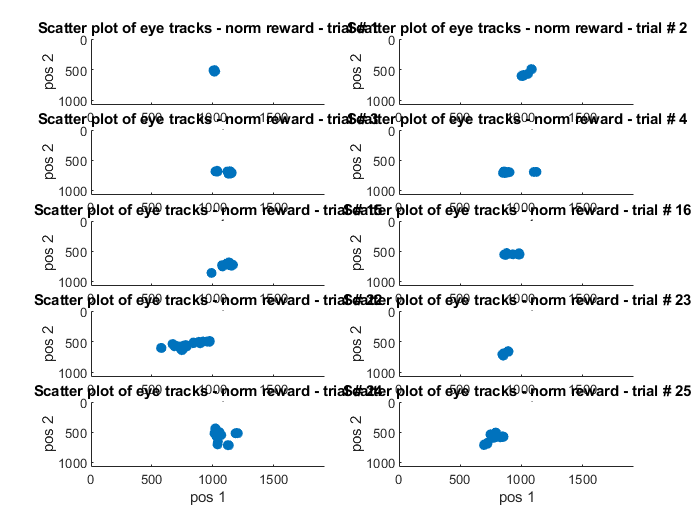

Number of samples = 266618Number of samples = 89653Number of samples = 89700Number of samples = 89551Number of samples = 89699Number of samples = 89564Number of samples = 89650Number of samples = 89742Number of samples = 89606Number of samples = 89690

reward_idx = [1 2 3 4 15 16 22 23 24 25];
figure;
for i=1:length(reward_idx)
    subplot(5,2,i, 'align');
    scatter_plot_eyeTrack(eye_tracks, "norm", reward_idx(i), 0);
end

function Eye_tracks = eye_track_data(rawData, start_idx, end_idx, reward_period_time)
    
    % count the number of trials for each reward type
    n_ext_reward = sum(reward_period_time==1);
    n_norm_reward = sum(reward_period_time==0.2);
    n_BG_reward = sum(reward_period_time==0.1);
    
    n_points = end_idx - start_idx + 1; % number of samples per trial
    n_traial = length(start_idx);
    
    Eye_tracks = struct( ...
            'ext_reward', -1 * ones(2, max(n_points), n_ext_reward), ...
            'norm_reward', -1 * ones(2, max(n_points), n_norm_reward), ...
            'BG_reward', -1 * ones(2, max(n_points), n_BG_reward)  ...
        );
    
    ext_rw_idx = 1;
    norm_rw_idx = 1;
    BG_rw_idx = 1;
    
    % Loop over each epoch and extract the data segment from the continuous data matrix
    for i = 1:n_traial
        
        % convert the location data from millivolts to pixels
        loc = [rawData(9, start_idx(i):end_idx(i))' rawData(10, start_idx(i):end_idx(i))'] ./ 1000;
        loc = (loc ./ 5) .* [960, 540];
        pos = loc + [960, 540];
          
        % assign the data segment to the corresponding reward type field
        switch reward_period_time(i)
            case 1
                Eye_tracks.ext_reward(:, 1:n_points(i), ext_rw_idx) = pos';
                ext_rw_idx = ext_rw_idx + 1;
            case 0.2
                Eye_tracks.norm_reward(:, 1:n_points(i), norm_rw_idx) = pos';
                norm_rw_idx = norm_rw_idx + 1;
            case 0.1
                Eye_tracks.BG_reward(:, 1:n_points(i), BG_rw_idx) = pos';
                BG_rw_idx = BG_rw_idx + 1;
        end
    end

end

function scatter_plot_eyeTrack(eye_tracks, reward_type, idx, isHistog)
    
    % select the data based on the reward type
    switch reward_type
        case "ext"
            data = eye_tracks.ext_reward(:,:, idx);
        case "norm"
            data = eye_tracks.norm_reward(:,:, idx);
        case "BG"
            data = eye_tracks.BG_reward(:,:, idx);
    end
    
    % trim and exract valid data since the fact that trials have different
    % sample lengths
    valid_ind = find(data >= 0);
    trimmed_data = data(valid_ind);
    trimmed_data = reshape(trimmed_data, size(data, 1), []);
    fprintf("Number of samples = %d", length(trimmed_data))
    
    % check if the user wants a scatter plot or a 2-D histogram
    if isHistog == 0
        scatter(trimmed_data(1, :), trimmed_data(2, :), 'filled');
    else
        histogram2(trimmed_data(1, :), trimmed_data(2, :), 'FaceColor','flat');
        colorbar;
    end
    
    set(gca, 'YDir', 'reverse')
    title("Scatter plot of eye tracks - " + reward_type + " reward - trial # " + num2str(idx))
    xlabel("pos 1")
    ylabel("pos 2")
    xlim([0 1920])
    ylim([0 1080])

end